start_point = [2, 3];
num = 2;
objective_func = @Akley;


                           Best        Current           Mean
Iteration   f-count         f(x)         f(x)         temperature
     0          1        7.98891        7.98891            100
    10         11        7.98891         21.174          56.88
    20         21        7.98891        18.7587        34.0562
    30         31        7.98891         21.161        20.3907
    40         41        7.98891        19.8812        12.2087
    50         51        7.98891         21.335        7.30977
    60         61        7.98891        21.7735        4.37663
    70         71        7.98891        21.4552        2.62045
    80         81        7.98891        20.8041        1.56896
    90         91        7.98891        20.1677       0.939395
   100        101        7.98891          21.98        0.56245
   110        111        7.98891        20.6238        0.33676
   120        121        7.98891        20.1026       0.201631
   130        131        7.98891        19.8564     

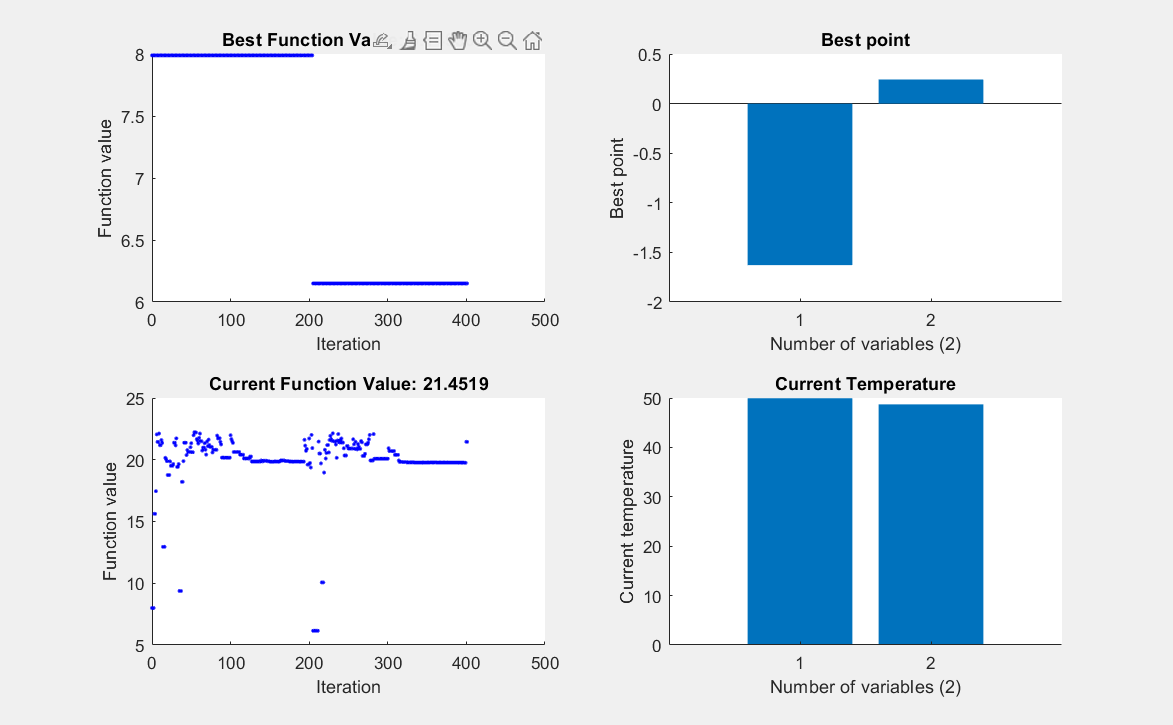

Maximum number of iterations exceeded: increase options.MaxIterations.


% Set nondefault solver options
options = optimoptions("simulannealbnd","MaxIterations",400,"Display","iter",...
    "PlotFcn",["saplotbestf","saplotbestx","saplotf","saplottemperature"]);

% Solve
[solution5,objectiveValue5] = simulannealbnd(@Akley,start_point,repmat(-32,...
    size(start_point)),repmat(32,size(start_point)),options);


% Clear variables
clearvars options

disp(objectiveValue5);

    6.1493



disp(solution5);

   -1.6284    0.2430

